# Confidence Regions Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path. To do so you can navigate to the StatBainz folder and fun the function addSB2path.m. Alternatively you can fill in the directory and run the code below.

statsbrainz_directory_pathloc = 'fill me in';
addpath(genpath(statsbrainz_directory_pathloc));

## Surface cope sets

sb_dir = statbrainz_maindir;
path4gifti_L = [sb_dir, '\BrainImages\Gifti_files\S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, '\BrainImages\Gifti_files\S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
load([sb_dir,'BrainImages\Real_data\hcpWM_surface.mat'])

#### Generate data

FWHM = 10;
nsubj = 50,

nsubj = 50

X = srf_noise(hcp_srf.lh, FWHM, nsubj);

50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done


X = X./std(X(:));
X = X.*hcp_data_std.lh;
X = X + hcp_data_mean.lh;

## FDR cope sets

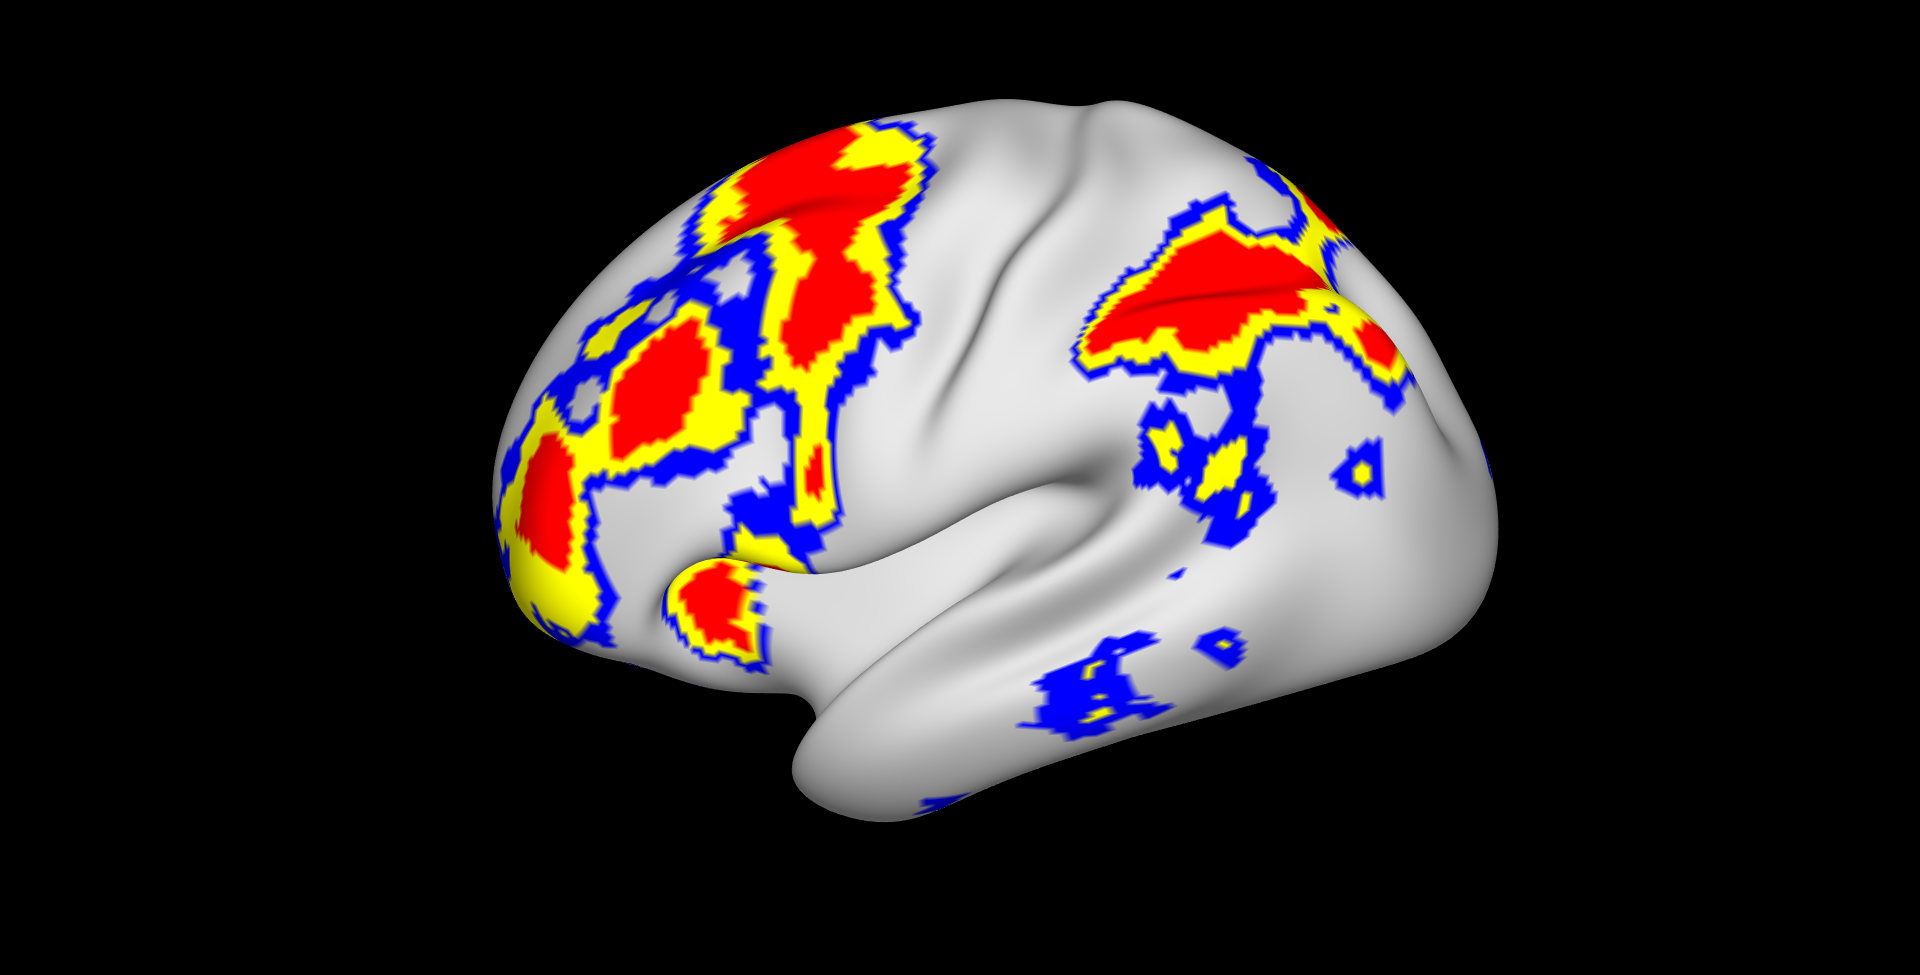

figure; set(gcf,'Visible','on')
c = 1;
[tstats, xbar] = mvtstat(X - c);
pvals = tstat2pval(nan2zero(tstats), 50 -1, 0);
upper_set = fdrBH( pvals );
lower_set = 1-fdrBH( 1 - pvals );
srf_cope_display(hcp_srf.lh,lower_set,upper_set, xbar, 0)